clc
close all
clear all
set(gcf,'Visible','on')

syms m p

f = logspace(0,6,1000);

w0 = 2*pi*1e3;
p = 1i*2*pi.*f;
H = 1./(1+2*m*(p/w0)+(p/w0).^2);

m1 = 0.1;

H1 = subs(H,m,m1);

G1 = 20*log10(abs(H1));

% subplot(2,1,1)
% semilogx(f,G1);
% title("Diagramme de Bode")
% 
% subplot(2,1,2)
% semilogx(f,angle(H1));
% title("Argument")


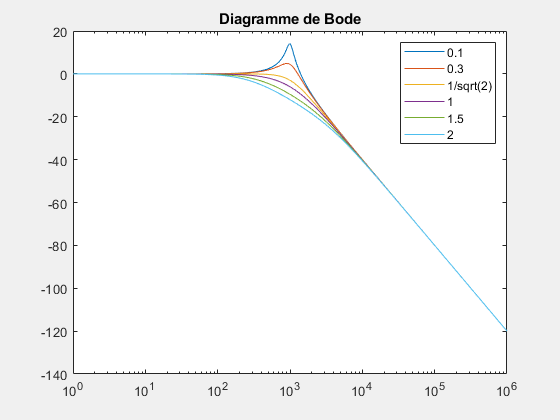

m2 = [0.1 0.3 1/sqrt(2) 1 1.5 2] ;
for i=1:length(m2)
    H2 = subs(H,m,m2(i));
    G2 = 20*log10(abs(H2));
    semilogx(f,G2);
    hold on;
end

title("Diagramme de Bode")
legend('0.1','0.3','1/sqrt(2)','1','1.5','2')